# Manipulability ellipsoid

## Shail Jadav 

https://shailjadav.github.io

       The manipulability ellipsoid is used to apprehend the manipulation representation, perceive the manipulator's ability to exert force and movement in specific configurations. Manipulation is defined using a jacobian matrix of the manipulator.

Let's understand Jacobian first.

clear;clc;close all

## Jacobian for RR Serial Chain

syms l1 l2 th1(t) th2(t) t


x=l1*cos(th1(t)) + l2*cos(th1(t)+th2(t));
y=l1*sin(th1(t)) + l2*sin(th1(t)+th2(t));

dx=diff(x,t);
dy=diff(y,t);


### **Velocity in X-direction**

pretty(simplify(dx))

                          /  d           d        \                   d
- l2 sin(th1(t) + th2(t)) | -- th1(t) + -- th2(t) | - l1 sin(th1(t)) -- th1(t)
                          \ dt          dt        /                  dt



### **Velocity in Y-direction**

pretty(simplify(dy))

                        /  d           d        \                   d
l2 cos(th1(t) + th2(t)) | -- th1(t) + -- th2(t) | + l1 cos(th1(t)) -- th1(t)
                        \ dt          dt        /                  dt



Jacobian matrix relates Joint-Space velocity and Cartesian-Space velocity.

#  
$$\dot{X} = J \dot{\theta}$$


J=[-l1*sin(th1(t))-l2*sin(th1(t)+th2(t)),-l2*sin(th1(t)+th2(t));l1*cos(th1(t))+l2*cos(th1(t)+th2(t)),l2*cos(th1(t)+th2(t))]

$$J = \left(\begin{array}{cc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}\right)$$

th1(t)=pi/4;
th2(t)=pi/2;
l1=1;
l2=1;

J=[-l1*sin(th1(t))-l2*sin(th1(t)+th2(t)),-l2*sin(th1(t)+th2(t));l1*cos(th1(t))+l2*cos(th1(t)+th2(t)),l2*cos(th1(t)+th2(t))]

$$J = \left(\begin{array}{cc} -\sqrt{2} & -\frac{\sqrt{2}}{2}\\ 0 & -\frac{\sqrt{2}}{2} \end{array}\right)$$

# Two critical observations about the jacobian matrix.

##  Jacobian matrix is not a strictly positive definite matrix. (Eigen values can be negative)

##  The jacobian matrix is not strictly orthogonal.

[a,b]=eig(J)

$$a = \left(\begin{array}{cc} 1 & -1\\ 0 & 1 \end{array}\right)$$

$$b = \left(\begin{array}{cc} -\sqrt{2} & 0\\ 0 & -\frac{\sqrt{2}}{2} \end{array}\right)$$

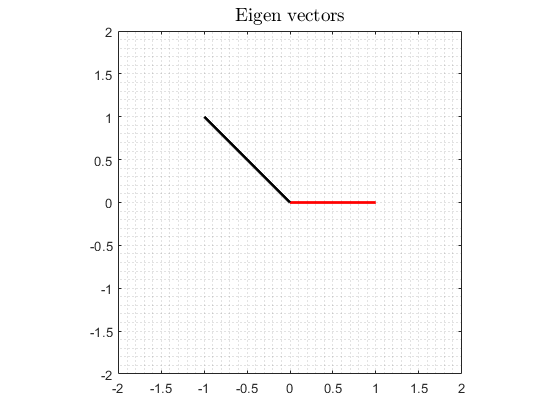

figure
plot([0 a(1,1)],[0 a(2,1)],'r','linewidth',2)
hold on
plot([0 a(1,2)],[0 a(2,2)],'k','linewidth',2)
axis([-2 2 -2 2])
axis square
grid minor
title('Eigen vectors','Interpreter',"latex","FontSize",14)

## `The orthogonal matrix has a unique property; when multiplied with its transpose, the resultant matrix will be an Identity matrix, which is not the case as we observe from the above simulations.Further, the Jacobian can be a rectangular matrix in redundant manipulators, where the concept of eigenvalues is limited.`

## `To resolve this, we can take an alternative approach in which we take the Jacobian matrix and multiply it with its transpose. The resultant matrix is symmetric and orthogonal, and positive semi-definite. The positive eigenvalues are essential to define the distance of the major and minor axis of ellipsoids, which comes from the square roots of eigenvalues of the Jacobian matrix multiplied with its transpose.`

[a,b]=eig(J*J')

$$a = \left(\begin{array}{cc} 2-\sqrt{5} & \sqrt{5}+2\\ 1 & 1 \end{array}\right)$$

$$b = \left(\begin{array}{cc} \frac{3}{2}-\frac{\sqrt{5}}{2} & 0\\ 0 & \frac{\sqrt{5}}{2}+\frac{3}{2} \end{array}\right)$$

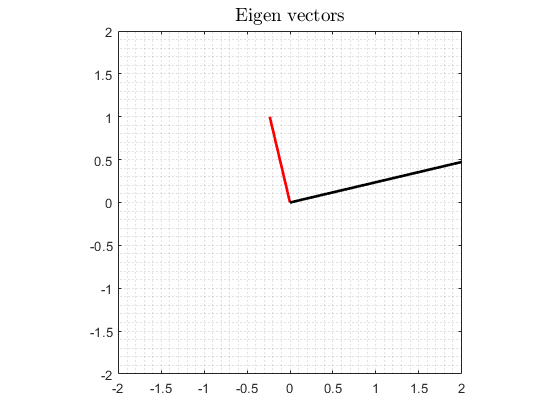

figure
plot([0 a(1,1)],[0 a(2,1)],'r','linewidth',2)
hold on
plot([0 a(1,2)],[0 a(2,2)],'k','linewidth',2)
axis([-2 2 -2 2])
axis square
grid minor
title('Eigen vectors','Interpreter',"latex","FontSize",14)

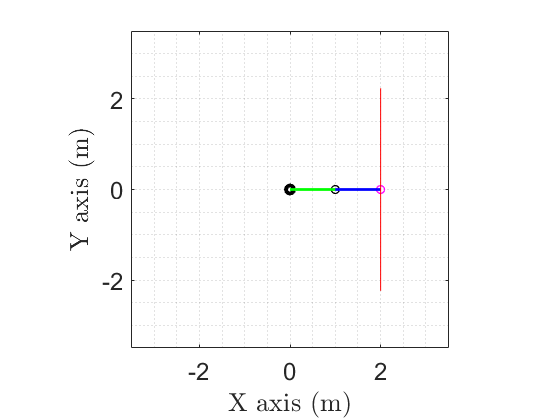

xi(1,:)=(0:pi/100:2*pi);
xi(2,:)=(2*pi:-pi/100:0);
figure()
c=1;
for i=1:1:length(xi)
    theta1=xi(1,i);
    theta2=xi(2,i);

    l1=1; %Input the l length
    l2=1; %Input the l length


    % Homogeneus transformation matrix
    H01 = [cos(theta1) -sin(theta1) 0 l1*cos(theta1);sin(theta1) cos(theta1) 0 l1*sin(theta1);0 0 1 0;0 0 0 1]; %Frame 0 to 1 tranformation
    H12 = [cos(theta2) -sin(theta2) 0 l2*cos(theta2);sin(theta2) cos(theta2) 0 l2*sin(theta2);0 0 1 0;0 0 0 1]; %Frame 1 to 2 tranformation

    H02=H01*H12;      %Frame 0 to 2 tranformation

    O=[0,0];
    P1=[H01(1,4) H01(2,4)];
    P2=[H02(1,4) H02(2,4)];

    Orn= atan2(H02(2,1),H02(1,1));  %Orientation of end effector
    Orn=(Orn)*(180/pi);

    plot(P1(1),P1(2),'ok','LineWidth',1)


    hold on
    plot(P2(1),P2(2),'om','LineWidth',1)
    plot(0,0,'ok','LineWidth',3)
    xlim([-3.5 3.5])
    ylim([-3.5 3.5])
    axis square
    grid minor
    plot([0 P1(1)], [0 P1(2)],'g','LineWidth',2)
    plot([P1(1) P2(1)], [P1(2) P2(2)],'b','LineWidth',2)

    J=[-l1*sin(theta1)-l2*sin(theta1+theta2),-l2*sin(theta1+theta2);l1*cos(theta1)+l2*cos(theta1+theta2),l2*cos(theta1+theta2)];

    [evt,evl]=eig(J*J');

    if(evl(2,2)>evl(1,1))
        MEV=[evt(1,2);evt(2,2)];
        a=sqrt(evl(2,2));
        b=sqrt(evl(1,1));
    end

    if(evl(2,2)<evl(1,1))
        MEV=[evt(1,1);evt(2,1)];
        a=sqrt(evl(1,1));
        b=sqrt(evl(2,2));
    end

    th= subspace([1;0],MEV);

    x0=P2(1); % x0,y0 ellipse centre coordinates
    y0=P2(2);
    t=-pi:0.01:pi;
    x56=a*cos(t);
    y56=b*sin(t);
    R5=[ cos(th) -sin(th) ; sin(th) cos(th)];
    P5= R5*[x56;y56];
    Xo= P5(1,:)+x0;
    Yo= P5(2,:)+y0;

    plot(Xo,Yo,'r')
    hold off
    %title(strcat('Time = ',num2str(t(i,1))),'Interpreter','latex')
    xlabel('X axis (m)','Interpreter','latex')
    ylabel('Y axis (m)','Interpreter','latex')
    set(gca,'FontSize',18)
    drawnow

    c=c+1;
end